 %  Copyright 2021 University of Padua, Italy
 %
 %  Licensed under the Apache License, Version 2.0 (the "License");
 %  you may not use this file except in compliance with the License.
 %  You may obtain a copy of the License at
 %
 %       http://www.apache.org/licenses/LICENSE-2.0
 %
 %  Unless required by applicable law or agreed to in writing, software
 %  distributed under the License is distributed on an "AS IS" BASIS,
 %  WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied.
 %  See the License for the specific language governing permissions and
 %  limitations under the License.
 %
 % 
 % @author Nicola Ferro

# Computation of one-way ANOVA on TREC 08, 1999, AdHoc

This example shows how to compare runs from TREC 08, 1999, AdHoc using one-way ANOVA.

## Setup

Load the performance score about the runs. The file contains:

- `ap` (or another measure name): a matrix where rows are topics and columns are runs; each cell contains the AP score for a run on a given topic;

- `runs`: an array of strings containing the identifiers of the runs; elements in the array are in the same order as columns on ap;

- `topics`: an array of strings containing the identifiers of the topics; elements in the array are in the same order as rows on ap;

% Load Average Precision data
% Other measures available are: P@10, nDCG, RBP
load C:\Users\Andrea\Desktop\MAGISTRALE\Anno1-sem2\SearchEngines\HWS\seupd2021-goldr\RUN\RUN2020\runtotonlymap.mat
% rename ap into measure to make follow-up processing the same for whatever
% measure we load
measure = runtotonlymap(1:49,:);
measure = table2array(measure)

measure =     0.6724    0.6724    0.6708    0.6711    0.6363
    0.3116    0.3116    0.3132    0.2886    0.1669
    0.3333    0.3333    0.3347    0.4506    0.2860
    0.3442    0.3356    0.3440    0.2592    0.1935
    0.2433    0.2485    0.2378    0.1157    0.1052
    0.3528    0.3356    0.3514    0.2101    0.1207
    0.2728    0.2729    0.2690    0.2189    0.1488
    0.1027    0.1027    0.1006    0.0240    0.0131
    0.2444    0.2487    0.2453    0.1734    0.0896
    0.2274    0.2187    0.2421    0.1698    0.1324



% remove the now useless ap matrix
clear runtotonlymap;

% the significance level
alpha = 0.05;

Reorder the measure by mean performance

% the mean for each run across the topics
% Note that if the measure is AP (Average Precision), 
% this is exactly MAP (Mean Average Precision) for each run
m1 = mean(measure);

% sort in descending order of mean score
[~, idx] = sort(m1, 'descend');

% re-order runs by descending mean of the measure
measure = measure(:, idx);
myruns = myruns(idx);

## One-way ANOVA

Compute the one-way ANOVA

% perform the ANOVA
[~, tbl, sts] = anova1(measure, myruns, 'off');

% display the ANOVA table
tbl

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[0.4863]}    {[  4]}    {[  0.1216]}    {[  3.9226]}    {[  0.0042]}
    {'Error'  }    {[7.4378]}    {[240]}    {[  0.0310]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[7.9241]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double}


Perform the multiple comparison

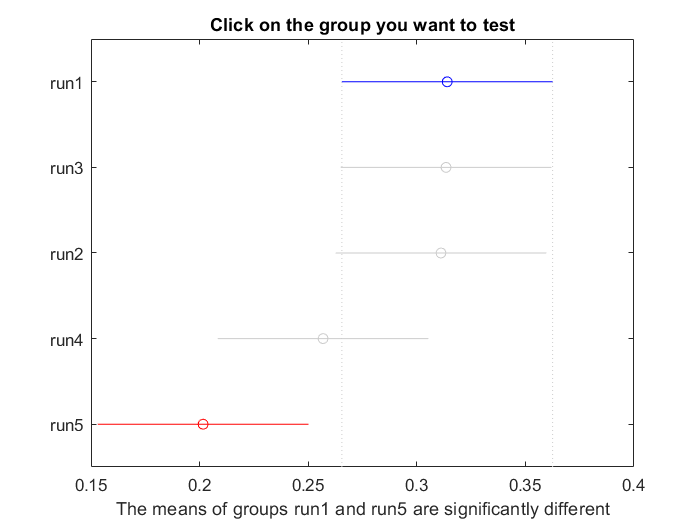

c = multcompare(sts, 'Alpha', alpha, 'Ctype', 'hsd'); 


% display the multiple comparisons
c

c =     1.0000    2.0000   -0.0965    0.0006    0.0976    1.0000
    1.0000    3.0000   -0.0941    0.0029    0.0999    1.0000
    1.0000    4.0000   -0.0399    0.0572    0.1542    0.4926
    1.0000    5.0000    0.0154    0.1124    0.2094    0.0137
    2.0000    3.0000   -0.0947    0.0023    0.0994    1.0000
    2.0000    4.0000   -0.0404    0.0566    0.1536    0.5026
    2.0000    5.0000    0.0148    0.1118    0.2089    0.0144
    3.0000    4.0000   -0.0427    0.0543    0.1513    0.5453
    3.0000    5.0000    0.0125    0.1095    0.2065    0.0177
    4.0000    5.0000   -0.0418    0.0552    0.1522    0.5279


## Two-way ANOVA - da finire

Compute the two-way ANOVA

% perform the ANOVA
[~, tbl2, sts2] = anova1(measure, myruns, 'off');

Error using  == 
Comparison between string and double is not supported.

Error in anova2 (line 50)
elseif reps == 1


% display the ANOVA table
tbl2

Perform the multiple comparison

c2 = multcompare(sts2, 'Alpha', alpha, 'Ctype', 'hsd'); 
c2